# レギュラーシーズンのEloレーティング(得失点割合)からプレイオフを予測する

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear;clc;close all

データを読み込む(prog_NBADataConcatenation.mlxを実行しておく)

load('../data/NBAResults.mat');

2018-19シーズンのチームと試合を抽出する．

seasonStartYearVal=2018;
ind = tbl_teams.SeasonStartYear==seasonStartYearVal;
tbl_teams_tmp=tbl_teams(ind,:);
numTeams=size(unique(tbl_teams_tmp.TeamName),1);

試合は訓練用(train)とテスト用(test)に分ける

ind = tbl_results.SeasonStartYear==seasonStartYearVal ...
    & tbl_results.isRegular;
tbl_results_train=tbl_results(ind,:);

ind = tbl_results.SeasonStartYear==seasonStartYearVal ...
    & tbl_results.isPlayoff;
tbl_results_test=tbl_results(ind,:);

### 比較のために勝敗や得失点も集計する

勝，負試合数，および得失点を集計する

集計用の変数を準備する

Wins=zeros(size(tbl_teams_tmp,1),1);
Loses=zeros(size(tbl_teams_tmp,1),1);
ScoresFor=zeros(size(tbl_teams_tmp,1),1);
ScoresAgainst=zeros(size(tbl_teams_tmp,1),1);

for n1=1:size(tbl_results_train,1)

それぞれの試合で両チームが何番に対応するかを見つける

    TeamANum=find(tbl_teams_tmp.TeamName==tbl_results_train.Home(n1));
    TeamBNum=find(tbl_teams_tmp.TeamName==tbl_results_train.Away(n1));

各チームの得失点を加える

    ScoresFor(TeamANum)=ScoresFor(TeamANum)+tbl_results_train.HomeScore(n1);
    ScoresFor(TeamBNum)=ScoresFor(TeamBNum)+tbl_results_train.AwayScore(n1);
    ScoresAgainst(TeamANum)=ScoresAgainst(TeamANum)+tbl_results_train.AwayScore(n1);
    ScoresAgainst(TeamBNum)=ScoresAgainst(TeamBNum)+tbl_results_train.HomeScore(n1);

得点の大小で場合分けし，勝・引分・負それぞれに加える

    if tbl_results_train.HomeScore(n1)>tbl_results_train.AwayScore(n1)
        Wins(TeamANum)=Wins(TeamANum)+1;
        Loses(TeamBNum)=Loses(TeamBNum)+1;
    elseif tbl_results_train.HomeScore(n1)<tbl_results_train.AwayScore(n1)
        Loses(TeamANum)=Loses(TeamANum)+1;
        Wins(TeamBNum)=Wins(TeamBNum)+1;
    end
end

勝利数，敗北数，勝率，得点割合の列を追加する

WinRatio=Wins./(Wins+Loses);
ScoreRatio=ScoresFor./(ScoresFor+ScoresAgainst);
tbl_teams_tmp=addvars(tbl_teams_tmp, Wins, Loses, WinRatio, ScoreRatio);

勝率→得失点割合の優先順でソートし，その順位を追加する

tbl_teams_tmp=sortrows(tbl_teams_tmp,{'WinRatio','ScoreRatio'},'descend');
RankByWins=(1:size(tbl_teams_tmp,1))';
tbl_teams_tmp=addvars(tbl_teams_tmp,RankByWins);

### Eloレーティング(得失点割合)を算出する

RatingEloScoreRatio=zeros(size(tbl_teams_tmp,1),1);

勝敗と得点割合それぞれの標準偏差を計算する

wl=tbl_results_train.HomeScore>tbl_results_train.AwayScore;
wl=[wl;1-wl];

s_ij=(tbl_results_test.HomeScore+1) ...
    ./(tbl_results_test.HomeScore+1+tbl_results_test.AwayScore+1);
s_ij=[s_ij;1-s_ij];

パラメータKを決める(勝敗のEloではK=4としたことを利用する)

K=4*log(10)/400*std(wl)/std(s_ij)

K = 0.3373

試合ごとにEloレーティングを更新する

for n1=1:size(tbl_results_train,1)
    homeNum= find(tbl_results_train.Home(n1) == tbl_teams_tmp.TeamName);
    awayNum= find(tbl_results_train.Away(n1) == tbl_teams_tmp.TeamName);
    homeRating= RatingEloScoreRatio(homeNum);
    awayRating= RatingEloScoreRatio(awayNum);
    p_ij=1/(1+exp(-(homeRating-awayRating)));
    s_i=tbl_results_train.HomeScore(n1);
    s_j=tbl_results_train.AwayScore(n1);
    s_ij=(s_i+1)/(s_i+1+s_j+1);
    RatingEloScoreRatio(homeNum)=RatingEloScoreRatio(homeNum)+K*(s_ij-p_ij);
    RatingEloScoreRatio(awayNum)=RatingEloScoreRatio(awayNum)-K*(s_ij-p_ij);
end
tbl_teams_tmp=addvars(tbl_teams_tmp, RatingEloScoreRatio);

勝率順位とEloレーティング(得点割合)の順位相関を計算する

corr(tbl_teams_tmp.WinRatio, tbl_teams_tmp.RatingEloScoreRatio, 'type','Kendall')

ans = 0.7562

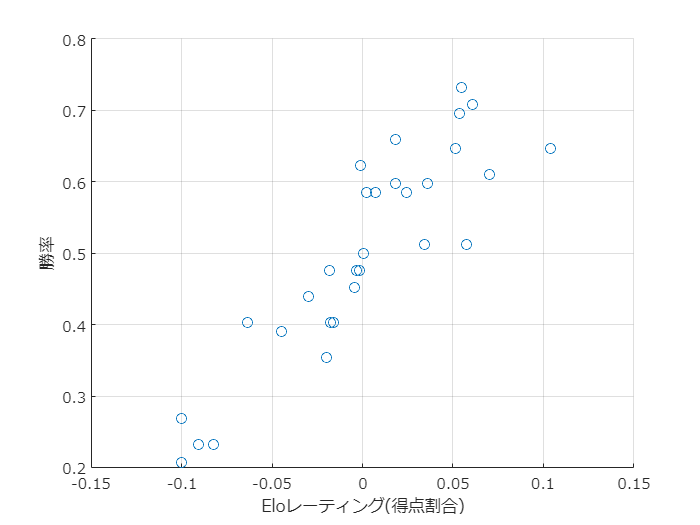

figure
scatter(tbl_teams_tmp.RatingEloScoreRatio, tbl_teams_tmp.WinRatio);
grid on;
set(gca,'fontname','メイリオ');
xlabel('Eloレーティング(得点割合)');ylabel('勝率');
exportgraphics(gcf,'fig_EloScoreRatioAndWinRatio.pdf');

プレイオフの結果を予測する

予測と実際の結果を格納する変数を定義する

PredictionByWin=zeros(size(tbl_results_test,1),1);
PredictionByEloScoreRatio=zeros(size(tbl_results_test,1),1);
ActualWin=zeros(size(tbl_results_test,1),1);
RateDiff=zeros(size(tbl_results_test,1),1);
ScoreRatio_mod=zeros(size(tbl_results_test,1),1);

試合ごとに実際の結果と予測を比較する

for n1=1:size(tbl_results_test,1)
    if tbl_results_test.HomeScore(n1)>tbl_results_test.AwayScore(n1)
        ActualWin(n1)=1;    %ホーム勝利を1と定義する
    else
        ActualWin(n1)=0;
    end

    ScoreRatio_mod(n1)= ...
        (tbl_results_test.HomeScore(n1)+1) ...
        / (tbl_results_test.HomeScore(n1)+1+tbl_results_test.AwayScore(n1)+1);

    TeamANum=find(tbl_teams_tmp.TeamName== tbl_results_test.Home(n1));
    TeamBNum=find(tbl_teams_tmp.TeamName== tbl_results_test.Away(n1));
    TeamARank=tbl_teams_tmp.RankByWins(TeamANum);
    TeamBRank=tbl_teams_tmp.RankByWins(TeamBNum);
    if TeamARank<TeamBRank
        PredictionByWin(n1)=1;
    else
        PredictionByWin(n1)=0;
    end

    TeamAElo=tbl_teams_tmp.RatingEloScoreRatio(TeamANum);
    TeamBElo=tbl_teams_tmp.RatingEloScoreRatio(TeamBNum);
    RateDiff(n1)=TeamAElo-TeamBElo;
    if TeamAElo>TeamBElo
        PredictionByEloScoreRatio(n1)=1;
    else
        PredictionByEloScoreRatio(n1)=0;
    end
end

レーティング差と得失点割合の散布図を描く

figure
hold on;grid on;
set(gca,'fontname','メイリオ');
scatter(RateDiff, ScoreRatio_mod);

ホームとアウェーを入れ替えたデータを追加する

scatter(-RateDiff, 1-ScoreRatio_mod);
RateDiff=[RateDiff;-RateDiff];

レーティング差の最小値と最大値の間を10個の点で分ける

bins=linspace(min(RateDiff),max(RateDiff),10);

レーティング差から予測される得失点割合(修正)を図示する

h_plot(1)=plot(bins, 1./(1+exp(-bins)),'r.-');

ScoreRatio_mod=[ScoreRatio_mod;1-ScoreRatio_mod];

それぞれのレーティング差の区間内での実際の得失点割合の平均を計算し，図示する．

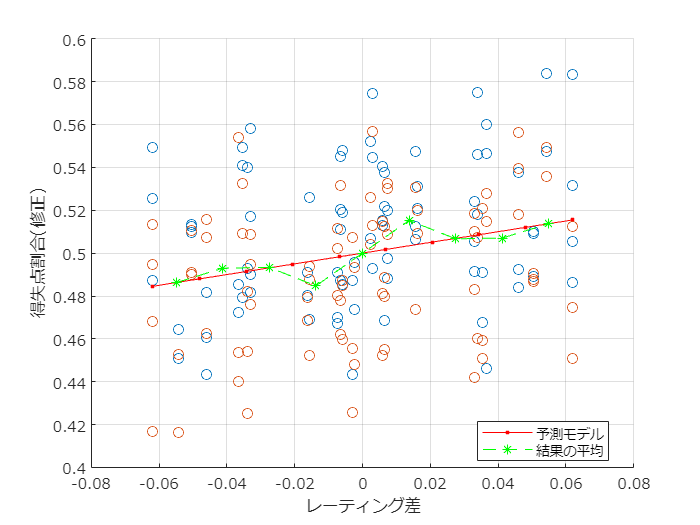

[catNum,edges]=discretize(RateDiff,bins);
plotData=[];
for n1=1:max(catNum)
    ind = catNum==n1;
    plotData=[plotData; mean(edges(n1:n1+1)) mean(ScoreRatio_mod(ind))];
end

h_plot(2)=plot(plotData(:,1),plotData(:,2),'g*--');
xlabel('レーティング差');
ylabel('得失点割合(修正)');
legend(h_plot,{'予測モデル','結果の平均'},'Location','best')
exportgraphics(gcf,'fig_NBA20182019PredictionByEloScoreRatio-RateDiff.pdf');

予測正解を判定する．

isPredictionCorrectByWin= ActualWin==PredictionByWin;
isPredictionCorrectByEloScoreRatio= ActualWin==PredictionByEloScoreRatio;

予測正解率を算出する

predictionAccuracyByWin=mean(isPredictionCorrectByWin)

predictionAccuracyByWin = 0.6951

predictionAccuracyByEloScoreRatio=mean(isPredictionCorrectByEloScoreRatio)

predictionAccuracyByEloScoreRatio = 0.6585

結果と予測，予測正解かどうかを図示する

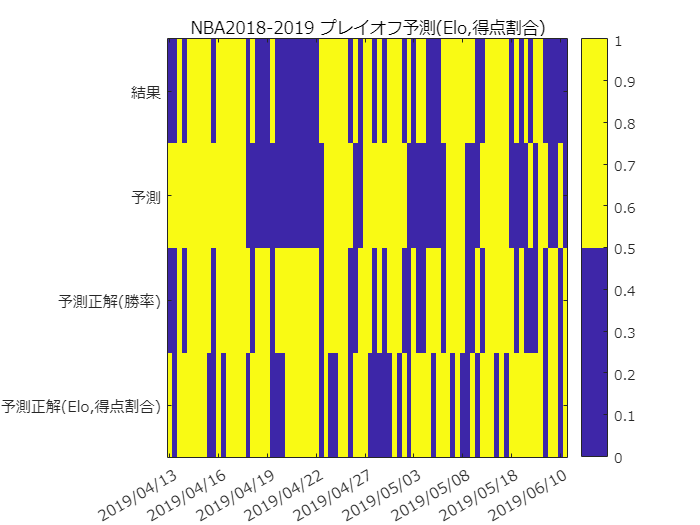

figure
imagesc([ActualWin PredictionByWin isPredictionCorrectByWin...
    isPredictionCorrectByEloScoreRatio]');
cmap=colormap(gca);
colormap(cmap([1,end],:));
colorbar;
set(gca,'fontname','メイリオ');
xticks(1:10:size(tbl_results_test,1));
xticklabels(string(tbl_results_test.Date(1:10:end)));
yticks(1:4);
yticklabels({'結果','予測','予測正解(勝率)','予測正解(Elo,得点割合)'});
title('NBA2018-2019 プレイオフ予測(Elo,得点割合)');
exportgraphics(gcf,'fig_NBA20182019PredictionByEloScoreRatio.pdf');

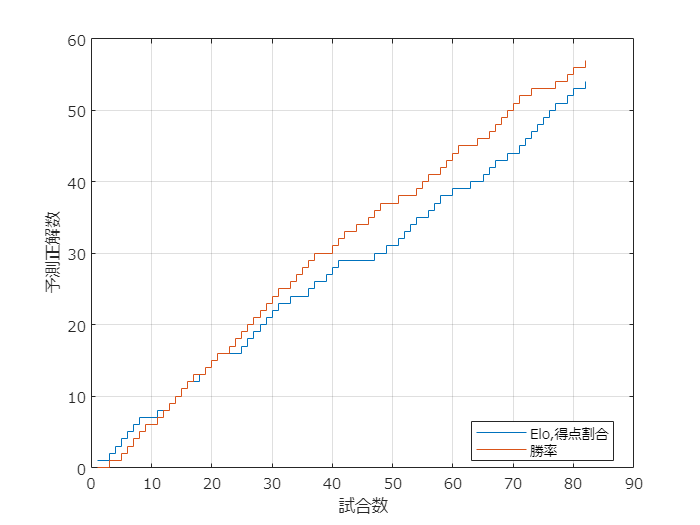

figure
stairs([cumsum(isPredictionCorrectByEloScoreRatio) cumsum(isPredictionCorrectByWin)]);
legend({'Elo,得点割合','勝率'},'Location','best')
grid on;
set(gca,'fontname','メイリオ');
xlabel('試合数');ylabel('予測正解数');
exportgraphics(gcf,'fig_NBA20182019CorrectPredictionsByEloScoreRatio.pdf');